# Tarea 1

s1 = audioread('test_period_70.wav');
s2 = audioread('Afonso_8khz.wav');
s3 = audioread('Gala_8khz.wav');

p = 10;

**Primero ejecutaremos el programa con los 3 archivos y para Ltrama = 160 y Lsubtrama=40**

Ltrama = 160;
Lsubtrama = 40;

% Truncamos las señales a un número entero de tramas
nframes1a = floor(length(s1)/Ltrama);
s1a = s1(1:nframes1a*Ltrama);
nframes2a = floor(length(s2)/Ltrama);
s2a = s2(1:nframes2a*Ltrama);
nframes3a = floor(length(s3)/Ltrama);
s3a = s3(1:nframes3a*Ltrama);

[sh1a_tr,B_1_a,G_1_a,AK_1_a,Tv_1_a,indv_1_a,bits_muestra_1_a,ep_1a,ead_1a,eest_1a]=celp_basico(s1,Ltrama,Lsubtrama,p);
[sh2a_tr,B_2_a,G_2_a,AK_2_a,Tv_2_a,indv_2_a,bits_muestra_2_a,ep_2a,ead_2a,eest_2a]=celp_basico(s2,Ltrama,Lsubtrama,p);
[sh3a_tr,B_3_a,G_3_a,AK_3_a,Tv_3_a,indv_3_a,bits_muestra_3_a,ep_3a,ead_3a,eest_3a]=celp_basico(s3,Ltrama,Lsubtrama,p);

sh1a = sh1a_tr.';
sh2a = sh2a_tr.';
sh3a = sh3a_tr.';

xaxis = 1000:2000;
figure(1)
max_lim = 1.1*max(s1a(1000:2000));
min_lim = 1.1*min(s1a(1000:2000));
subplot(311); plot(xaxis,s1a(1000:2000)); title("Señal original"); ylim([min_lim,max_lim]);
max_lim = 1.1*max(sh1a(1000:2000));
min_lim = 1.1*min(sh1a(1000:2000));
subplot(312); plot(xaxis,sh1a(1000:2000)); title("Señal reconstruida"); ylim([min_lim,max_lim])
max_lim = 1.1*max(s1a(1000:2000)-sh1a(1000:2000));
min_lim = 1.1*min(s1a(1000:2000)-sh1a(1000:2000));
subplot(313); plot(xaxis,(s1a(1000:2000)-sh1a(1000:2000))); title("Error(s-sh)"); ylim([min_lim,max_lim])

xaxis = 10000:11000;
figure(2)
max_lim = 1.1*max(s2a(10000:11000));
min_lim = 1.1*min(s2a(10000:11000));
subplot(311); plot(xaxis,s2a(10000:11000)); title("Señal original"); ylim([min_lim,max_lim]);
max_lim = 1.1*max(sh2a(10000:11000));
min_lim = 1.1*min(sh2a(10000:11000));
subplot(312); plot(xaxis,sh2a(10000:11000)); title("Señal reconstruida"); ylim([min_lim,max_lim])
max_lim = 1.1*max(s2a(10000:11000)-sh2a(10000:11000));
min_lim = 1.1*min(s2a(10000:11000)-sh2a(10000:11000));
subplot(313); plot(xaxis,(s2a(10000:11000)-sh2a(10000:11000))); title("Error (s-sh)"); ylim([min_lim,max_lim])

xaxis = 16500:17500;
figure(3)
max_lim = 1.1*max(s3a(16500:17500));
min_lim = 1.1*min(s3a(16500:17500));
subplot(311); plot(xaxis,s3a(16500:17500)); title("Señal original"); ylim([min_lim,max_lim]);
max_lim = 1.1*max(sh3a(16500:17500));
min_lim = 1.1*min(sh3a(16500:17500));
subplot(312); plot(xaxis,sh3a(16500:17500)); title("Señal reconstruida"); ylim([min_lim,max_lim])
max_lim = 1.1*max(s3a(16500:17500)-sh3a(16500:17500));
min_lim = 1.1*min(s3a(16500:17500)-sh3a(16500:17500));
subplot(313); plot(xaxis,(s3a(16500:17500)-sh3a(16500:17500))); title("Error (s-sh)"); ylim([min_lim,max_lim])

**Ahora ejecutaremos el programa con los 3 archivos y para Ltrama = 240 y Lsubtrama=60**

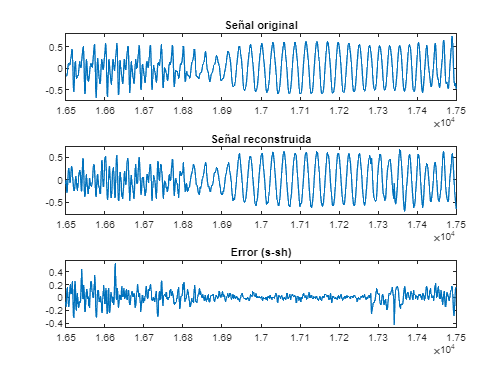

Ltrama = 240;
Lsubtrama = 60;

% Truncamos las señales a un número entero de tramas
nframes1b = floor(length(s1)/Ltrama);
s1b = s1(1:nframes1b*Ltrama);
nframes2b = floor(length(s2)/Ltrama);
s2b = s2(1:nframes2b*Ltrama);
nframes3b = floor(length(s3)/Ltrama);
s3b = s3(1:nframes3b*Ltrama);

[sh1b_tr,B_1_b,G_1_b,AK_1_b,Tv_1_b,indv_1_b,bits_muestra_1_b,ep_1b,ead_1b,eest_1b]=celp_basico(s1,Ltrama,Lsubtrama,p);
[sh2b_tr,B_2_b,G_2_b,AK_2_b,Tv_2_b,indv_2_b,bits_muestra_2_b,ep_2b,ead_2b,eest_2b]=celp_basico(s2,Ltrama,Lsubtrama,p);
[sh3b_tr,B_3_b,G_3_b,AK_3_b,Tv_3_b,indv_3_b,bits_muestra_3_b,ep_3b,ead_3b,eest_3b]=celp_basico(s3,Ltrama,Lsubtrama,p);

sh1b = sh1b_tr.';
sh2b = sh2b_tr.';
sh3b = sh3b_tr.';

xaxis = 1000:2000;
figure(4)
max_lim = 1.1*max(s1b(1000:2000));
min_lim = 1.1*min(s1b(1000:2000));
subplot(311); plot(xaxis,s1b(1000:2000)); title("Señal original"); ylim([min_lim,max_lim]);
max_lim = 1.1*max(sh1b(1000:2000));
min_lim = 1.1*min(sh1b(1000:2000));
subplot(312); plot(xaxis,sh1b(1000:2000)); title("Señal reconstruida"); ylim([min_lim,max_lim])
max_lim = 1.1*max(s1b(1000:2000)-sh1b(1000:2000));
min_lim = 1.1*min(s1b(1000:2000)-sh1b(1000:2000));
subplot(313); plot(xaxis,(s1b(1000:2000)-sh1b(1000:2000))); title("Error (s-sh)"); ylim([min_lim,max_lim])

xaxis = 10000:11000;
figure(5)
max_lim = 1.1*max(s2b(10000:11000));
min_lim = 1.1*min(s2b(10000:11000));
subplot(311); plot(xaxis,s2b(10000:11000)); title("Señal original"); ylim([min_lim,max_lim]);
max_lim = 1.1*max(sh2b(10000:11000));
min_lim = 1.1*min(sh2b(10000:11000));
subplot(312); plot(xaxis,sh2b(10000:11000)); title("Señal reconstruida"); ylim([min_lim,max_lim])
max_lim = 1.1*max(s2b(10000:11000)-sh2b(10000:11000));
min_lim = 1.1*min(s2b(10000:11000)-sh2b(10000:11000));
subplot(313); plot(xaxis,(s2b(10000:11000)-sh2b(10000:11000))); title("Error (s-sh)"); ylim([min_lim,max_lim])

xaxis = 16500:17500;
figure(6)
max_lim = 1.1*max(s3b(16500:17500));
min_lim = 1.1*min(s3b(16500:17500));
subplot(311); plot(xaxis,s3b(16500:17500)); title("Señal original"); ylim([min_lim,max_lim]);
max_lim = 1.1*max(sh3b(16500:17500));
min_lim = 1.1*min(sh3b(16500:17500));
subplot(312); plot(xaxis,sh3b(16500:17500)); title("Señal reconstruida"); ylim([min_lim,max_lim])
max_lim = 1.1*max(s3b(16500:17500)-sh3b(16500:17500));
min_lim = 1.1*min(s3b(16500:17500)-sh3b(16500:17500));
subplot(313); plot(xaxis,(s3b(16500:17500)-sh3b(16500:17500))); title("Error (s-sh)"); ylim([min_lim,max_lim])

**SNR global, segmental y por tramas para 'test_period_70.wav' (2 subplots, para los 2 valores de Ltrama y Lsubtrama)**

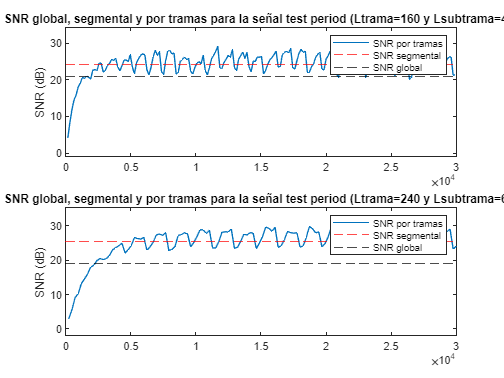

S_1a = SNR(s1a,sh1a);
S_1b = SNR(s1b,sh1b);

[Sseg_1a,Sm_1a,m_1a] = SNRS(s1a,sh1a,160);
[Sseg_1b,Sm_1b,m_1b] = SNRS(s1b,sh1b,240);

figure(7)
subplot(211)
plot(m_1a,Sm_1a);
hold on
yline(Sseg_1a,'r--')
hold on
yline(S_1a,'k--')
hold off
title("SNR global, segmental y por tramas para la señal test period (Ltrama=160 y Lsubtrama=40)")
ylim([min(Sm_1a)-5,max(Sm_1a)+5])
ylabel('SNR (dB)')
legend('SNR por tramas','SNR segmental','SNR global')
subplot(212)
plot(m_1b,Sm_1b);
hold on
yline(Sseg_1b,'r--')
hold on
yline(S_1b,'k--')
hold off
title("SNR global, segmental y por tramas para la señal test period (Ltrama=240 y Lsubtrama=60)")
ylim([min(Sm_1b)-5,max(Sm_1b)+5])
ylabel('SNR (dB)')
legend('SNR por tramas','SNR segmental','SNR global')

**SNR global, segmental y por tramas para 'Afonso_8khz.wav' (2 subplots, para los 2 valores de Ltrama y Lsubtrama)**

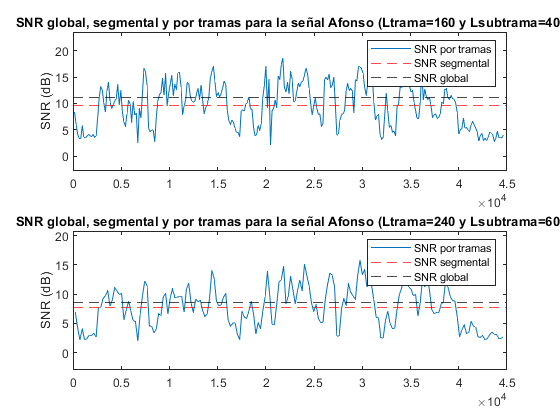

S_2a = SNR(s2a,sh2a);
S_2b = SNR(s2b,sh2b);

[Sseg_2a,Sm_2a,m_2a] = SNRS(s2a,sh2a,160);
[Sseg_2b,Sm_2b,m_2b] = SNRS(s2b,sh2b,240);

figure(8)
subplot(211)
plot(m_2a,Sm_2a);
hold on
yline(Sseg_2a,'r--')
hold on
yline(S_2a,'k--')
hold off
title("SNR global, segmental y por tramas para la señal Afonso (Ltrama=160 y Lsubtrama=40)")
ylim([min(Sm_2a)-5,max(Sm_2a)+5])
ylabel('SNR (dB)')
legend('SNR por tramas','SNR segmental','SNR global')
subplot(212)
plot(m_2b,Sm_2b);
hold on
yline(Sseg_2b,'r--')
hold on
yline(S_2b,'k--')
hold off
title("SNR global, segmental y por tramas para la señal Afonso (Ltrama=240 y Lsubtrama=60)")
ylim([min(Sm_2b)-5,max(Sm_2b)+5])
ylabel('SNR (dB)')
legend('SNR por tramas','SNR segmental','SNR global')

**SNR global, segmental y por tramas para 'Gala_8khz.wav' (2 subplots, para los 2 valores de Ltrama y Lsubtrama)**

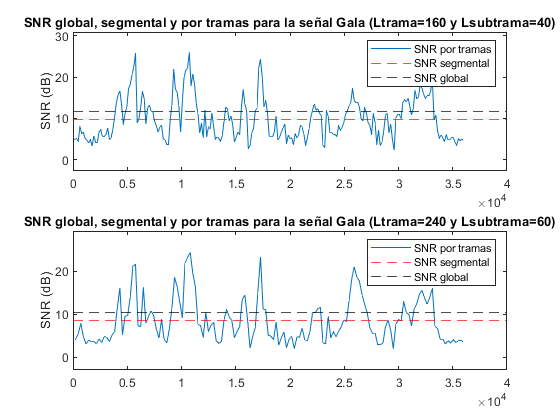

S_3a = SNR(s3a,sh3a);
S_3b = SNR(s3b,sh3b);

[Sseg_3a,Sm_3a,m_3a] = SNRS(s3a,sh3a,160);
[Sseg_3b,Sm_3b,m_3b] = SNRS(s3b,sh3b,240);

figure(9)
subplot(211)
plot(m_3a,Sm_3a);
hold on
yline(Sseg_3a,'r--')
hold on
yline(S_3a,'k--')
hold off
title("SNR global, segmental y por tramas para la señal Gala (Ltrama=160 y Lsubtrama=40)")
ylim([min(Sm_3a)-5,max(Sm_3a)+5])
ylabel('SNR (dB)')
legend('SNR por tramas','SNR segmental','SNR global')
subplot(212)
plot(m_3b,Sm_3b);
hold on
yline(Sseg_3b,'r--')
hold on
yline(S_3b,'k--')
hold off
title("SNR global, segmental y por tramas para la señal Gala (Ltrama=240 y Lsubtrama=60)")
ylim([min(Sm_3b)-5,max(Sm_3b)+5])
ylabel('SNR (dB)')
legend('SNR por tramas','SNR segmental','SNR global')